# Práctica 2: Número de particiones

En esta práctica se introduce la recursividad como manera de programación y se aplica al contaje de número de particiones de un conjunto.

**Borrón y cuenta nueva!!**

clc, clear, close all

## 1. Recursividad

La función factorial de un número natural n la podemos ver de dos formas:

a) $n! = n \cdot (n-1)\cdots 2 \cdot 1$

b) $n! = n \cdot (n-1)!$

La forma b) emplea en la definición del factorial la propia función factorial pero aplicada a un valor  diferente del parámetro de entrada. La definición b) es una definición recursiva de la función factorial.

### EJERCICIO: Calculo del factorial de un número

Implementar la función factorial utilizando un enfoque iterativo (factorial_a()) y uno recursivo (factorial_b). Probar su correcto funcionamiento calculando 5!

% Definir la función MATLAB factorial_a y factorial_b  en un fichero aparte
factorial_a(5)

ans = 120

factorial_b(5)

ans = 120

## 2. Número de particiones

Supongamos que tenemos un conjunto $A$. Diremos que los subconjuntos $A_1,A_2, \ldots A_k$ constituyen una partición de $A$ si son disjuntos dos a dos $A_i\cap A_j=\{ \emptyset\}$y la unión de todos ellos da el conjunto $A$, i.e. $A=\cup_{i=1} ^kA_i$. Por ejemplo si $A=\{1,2,3,\ldots,10 \}$ una partición suya es . $A_1=\{1,2,3\}, A_2=\{10\}, A_3=\{4,5,6,7,8,9\}$. Este es un ejemplo de una partición de un conjunto de n=10 elementos constituida por $k=3$ subconjuntos. La cantidad de posibles particiones que pueden ser generadas cuando un conjunto de $n$ elementos se divide en $k$ partes se denomina como número de **Stirling de 2ª especie **y lo denotamos por

            $S_{n,k}$.

Vamos a justificar una fórmula recursiva para calcular $S_{n,k}$. Supongamos que tenemos n-1 objetos azules y añadimos un nuevo objeto rojo. Tal y como muestral la figura.

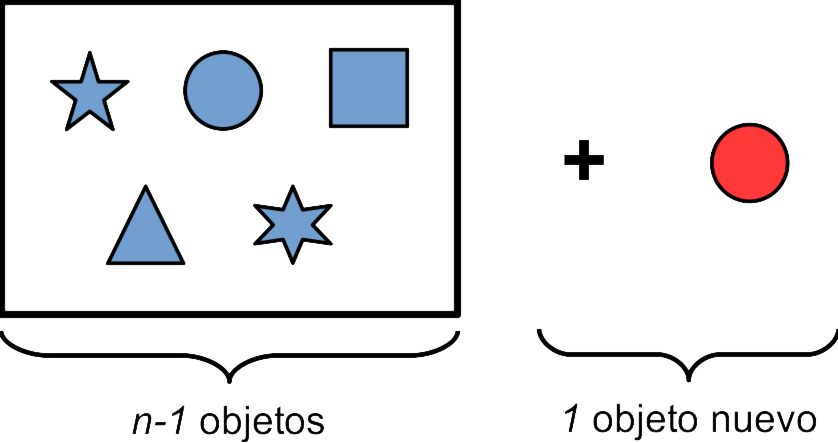

La siguiente figura muestra como a partir de una partición de los objetos azules podemos construir una nueva partición de todos los objetos (azules + rojo) con k componentes. Se plantea dos situaciones:

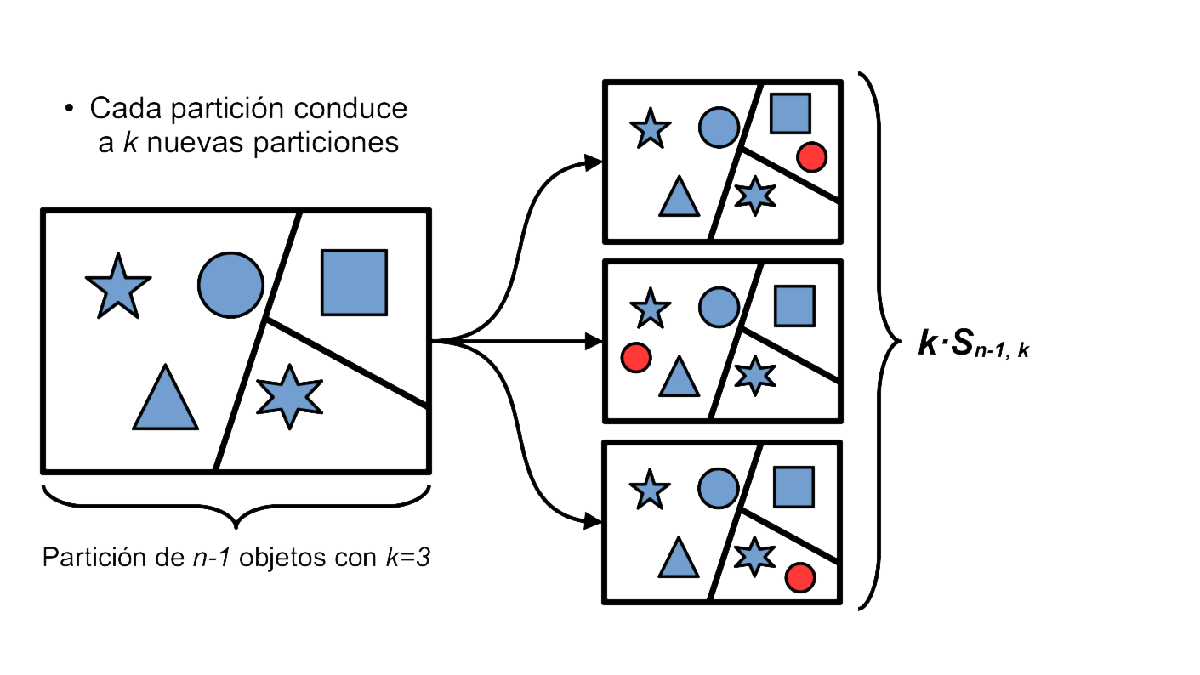

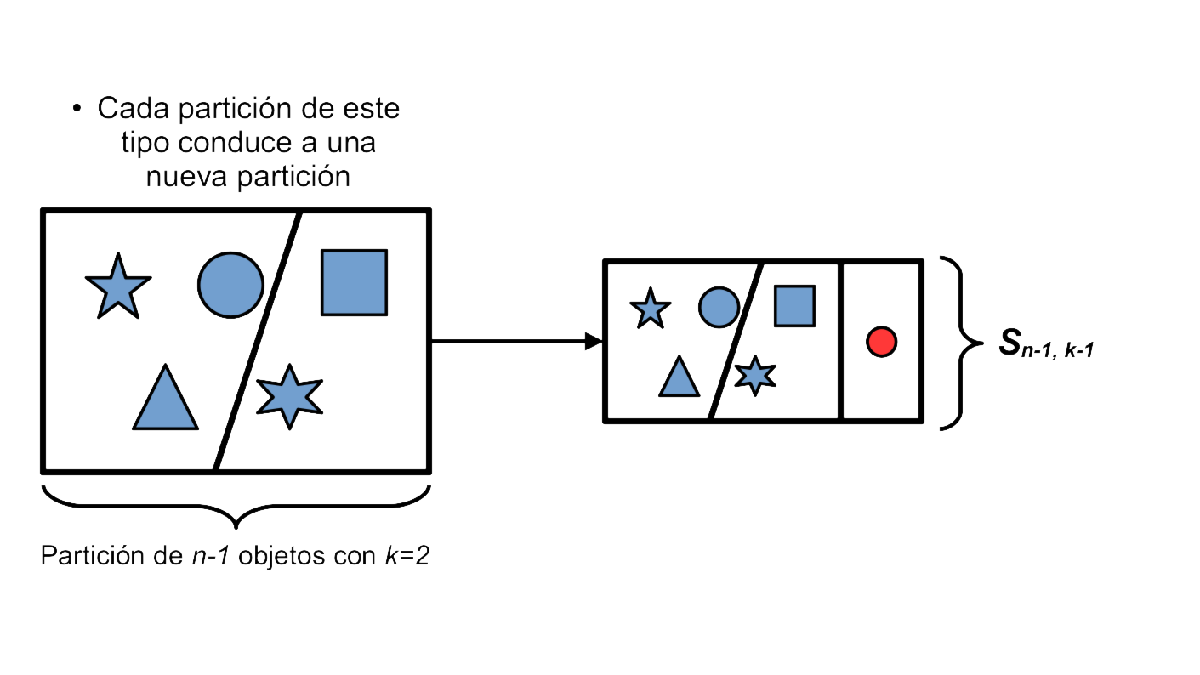

Observando el dibujo anterior se tiene:

            
$$S_{n,k}=kS_{n-1,k}+S_{n-1,k-1}$$


### EJERCICIO: Números de Stirling de segunda especie

- Programa recursivamente una función para calcular los números de Stirling $S_{n,k}$. ¿Cuanto vale $S_{k,k}$? ¿Cuanto vale $S_{n,1}$?

%% Programar en un fichero aparte la función Stirling2

%% Calcular S_5,3 del ejemplo
Stirling2(5,3)

ans = 25

### EJERCICIO: Números de Bell

Como se ha indicado anteriormente, los números de Stirling de segunda especie $S_{n,k}$ cuentan el número de posibles particiones cuando un conjunto de $n$ elementos se divide en $k$ partes.

El número total de particiones de un conjunto de $n$ objetos es por tanto la suma de los números de Stirling para todos los valores posibles de $k$, es decir:

                                        
$$B_n=\sum_{k=1} ^n S_{n,k}.$$


Estos números reciben el nombre de números de Bell.

- Haz una función para calcular Bell(n).

- ¿Cuál es el valor de Bell(5)?

%% Programar en un fichero aparte el función Bell(n)

%% Calcular Bell(5) 
Bell(5)

ans = 52

- ¿Los números de Bell tienen  crecimiento polinomial o exponencial?

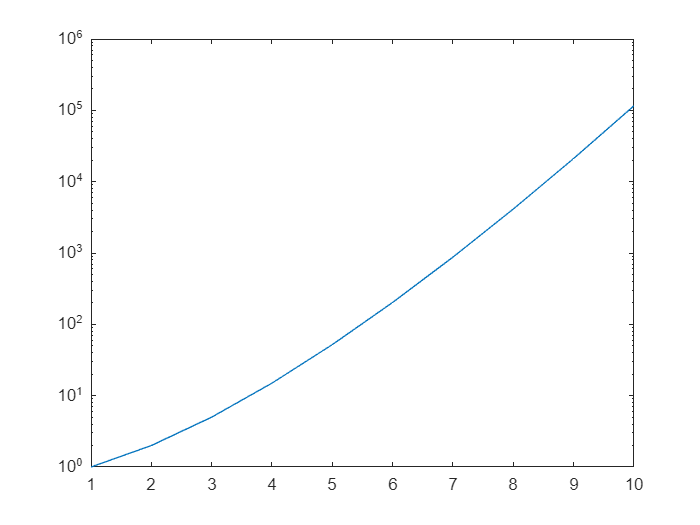

%% Completar con el código correspondiente
for n = 1:10
    y(n)=Bell(n);
end
semilogy(1:10,y);